# Solution Guide

There are a broad range of possible solutions, but essentially the students should recreate the steps used in the Develop section with a new set of data (a different column of data)

Here is an example of what that would look like:

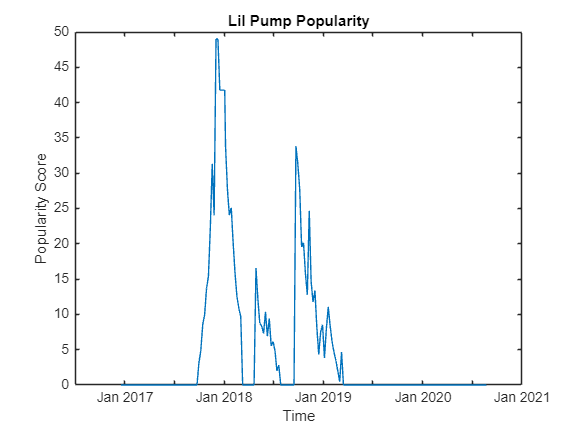

clc;clear;
data = readcell("/MATLAB Drive/MATLAB - Section 04 (Teacher - File Share)/Data/lilpumpdata.xlsx");
rank = data(2:end,6); %% the second argument here may vary depending
                      %% on the students choice, 6 is best option
date = data(2:end,3);

cell_array = [date, rank];
data_table = cell2table(cell_array,'VariableNames',{'Date','Rank'});
music_timetable = table2timetable(data_table);
plot(music_timetable.Date,music_timetable.Rank);
title("Lil Pump Popularity");
xlabel("Time");
ylabel("Popularity Score");